% Treffe eine Vorhersage für einzelne Datenpunkte. 
% Trainingsdaten werden in Test und Training aufgeteilt.
% guter erster Ansatz um den GP Algorithmus zu testen
close
clear
clc

 load('trainingsdaten.mat')
 time = (0 : 0.1: length(x)/10).';
    
    % Testdaten
    xS = x(15 : 20:end,:);
    yS = y(15 : 20:end,1);
    uS = u(15 : 20:end,1);
    dxS = dx(15 : 20:end,1);
    uxS = [uS, xS];
    tS = time(15 : 20:end,:);
    nS = length(xS);
    
    %Trainingsdaten
    x = x(10 : 10:end,:);
    y = y(10 : 10:end,1);
    u = u(10 : 10:end,1);
    dx = dx(10 : 10:end,1);
    ux = [u,x];
    t = time(10 : 10:end,:);
    n = length(x);
    
    % Hyperparameter
    sigmaN = 0.35;
    sigmaF=100;
    l = 10;


axis = (1:1:nS).';

kS = zeros(n,1);

%Hyperparameter lernen 
% meanfunc = [];
% covfunc = @covSEiso;
% likfunc = @likGauss;
% hyp = struct('mean',[],'cov',[0,0],'lik',-0.45);
% 
K_ux = CovMatrix(ux,sigmaF,l);
K_dx = (K_ux+sigmaN*eye(n))^-1;
% logLikelihood_V1(dx,K_ux,sigmaN);
% logLikelihood_V2(dx,K_ux,sigmaN);
% [likeLog, dLikeLog] = gp(hyp, @infGaussLik, meanfunc, covfunc, likfunc, ux,dx);
% 
% hyp2 = minimize(hyp, @gp,-100,@infGaussLik,meanfunc, covfunc, likfunc,ux, dx);%W, sigmaF, sigmsN
%  l = (exp(hyp2.cov(1)));
% sigmaF = exp(hyp2.cov(2));
% sigmaN = exp(hyp2.lik(1));
% [likeLog, dLikeLog] = gp(hyp, @infGaussLik, meanfunc, covfunc, likfunc, ux,dx);
% logLikelihood_V1(dx,K_ux,sigmaN);
% logLikelihood_V2(dx,K_ux,sigmaN);

% GP über fct von Rasmussen 
%[mu, s2] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, ux, dx, uxS);

%GP über eigene Funktionen
mu_dx = zeros(size(uS));
s2 = zeros(size(mu_dx));
for i = 1:nS
  [mu_dx(i),s2(i)] = GPpredict_V1(K_dx,ux,dx,uxS(i,:),sigmaF,sigmaN,l);  
end
mu = mu_dx+ xS(:,1); % Erwartungswert ist dx, daher Addition mit dem vorheringen Wert


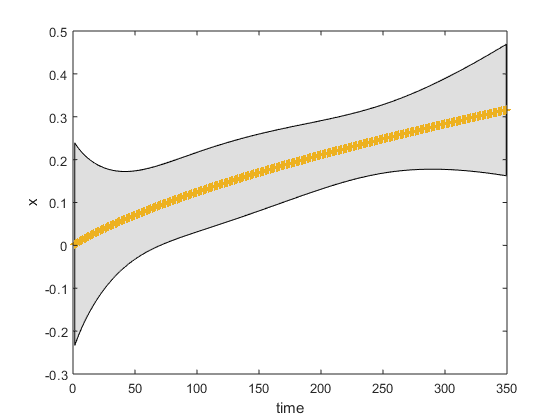

% Plotte Trsainingsdaten und Testdaten mit Varianz  
f = [mu+2*sqrt(s2); flipdim(mu-2*sqrt(s2),1)];
  
  %figure(1)
  fill([tS;flipdim(tS,1)], f, [7 7 7]/8)
  hold on; 
  plot(tS,mu); 
  plot(t,dx+x(:,1), '+')
  xlabel('time')
  ylabel('x')

% Plotte dx für Trainings und Testdaten  
hold off; 

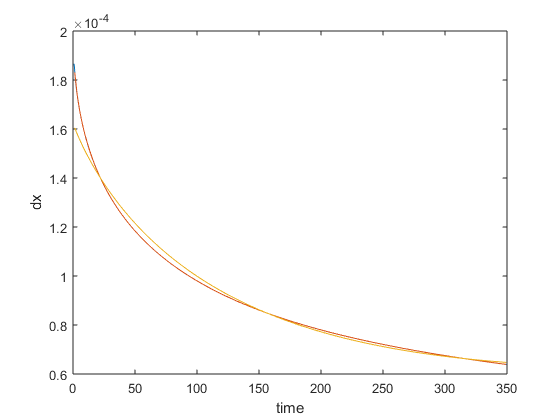

%figure(2)
plot(t,dx,tS,dxS,tS,mu_dx);
xlabel('time')
ylabel('dx')